**Börsenkurs als 1D Brownische Bewegung**

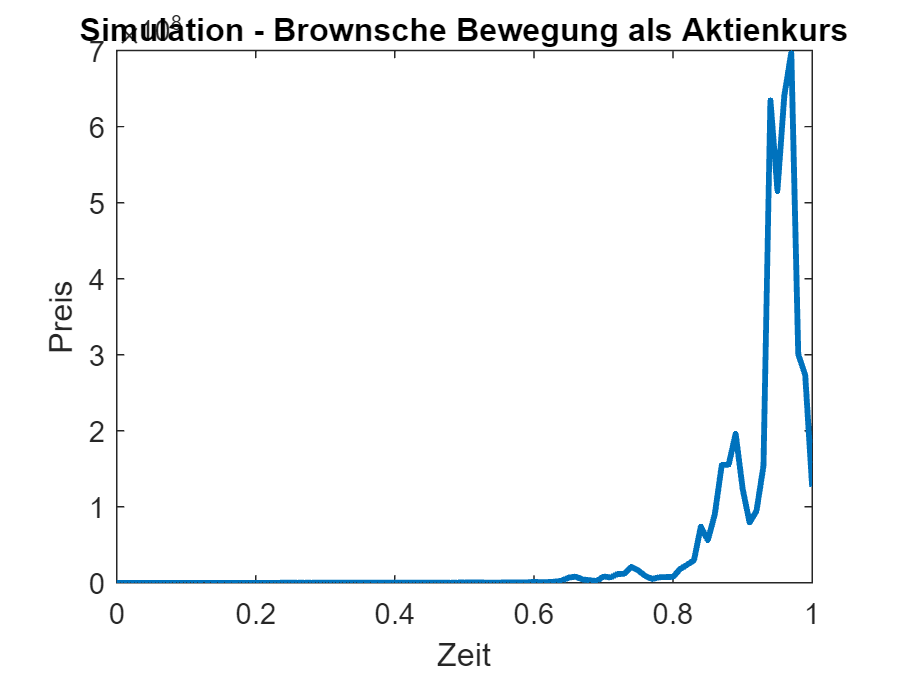

t = 1;
N = 100;
dt = t/N; 
sigma = 5; 
S0 = 1; %Anfangspreis


dB = sqrt(dt)*randn(1,N); %Weiner-Prozess
W = cumsum(dB); 
S = S0*exp((sigma^2/2)*dt*(1:N) + sigma*W);

plot(0:dt:t,[S0,S],'linewidth',2)
xlabel('Zeit')
ylabel('Preis')
title('Simulation - Brownsche Bewegung als Aktienkurs')

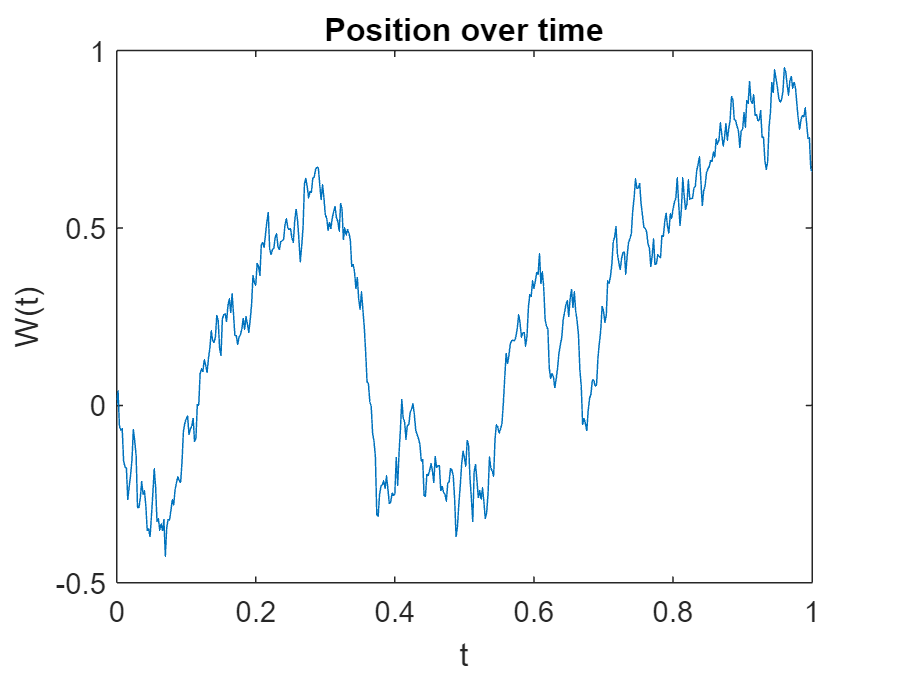

randn('state',100)
T = 1;
N = 500;
dt = T/N;
dW = sqrt(dt) * randn(1,N);
W = cumsum(dW);
plot(0:dt:T,[0,W])
xlabel('t')
ylabel('W(t)')
title('Position over time')

**2D Brownische Bewegung**

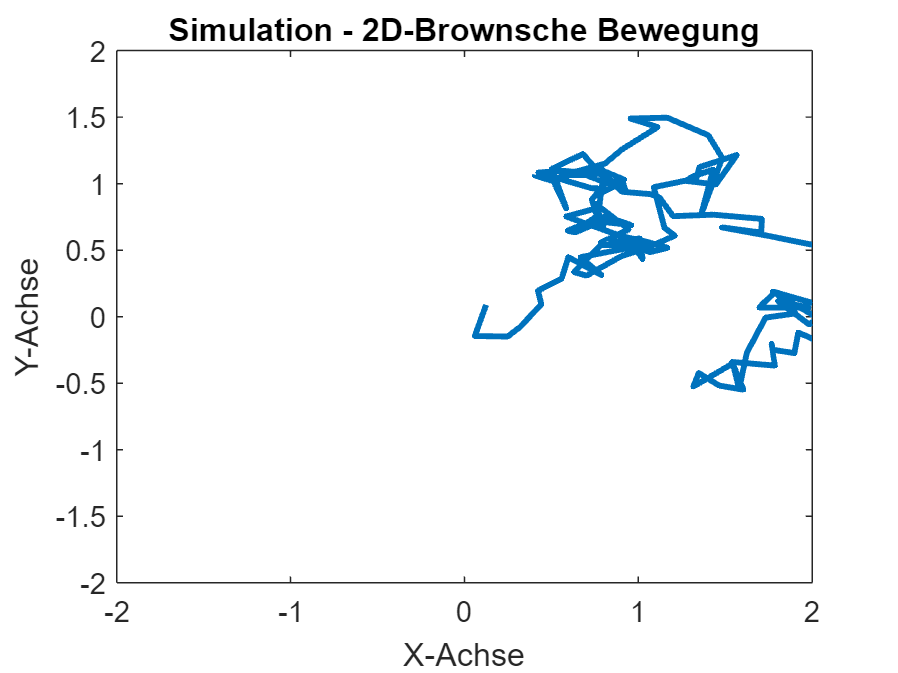

t = 1;
N = 200;
dt = t/N;
sigma = 2;
XY0 = [0,0];

dB = sqrt(dt)*randn(2,N);
W = cumsum(dB,2);
S = XY0' + sigma*W;

plot(S(1,:),S(2,:),'linewidth',2)
axis_max = 2;
xlim([-axis_max, axis_max]);
ylim([-axis_max, axis_max]);
xlabel('X-Achse')
ylabel('Y-Achse')
title('Simulation - 2D-Brownsche Bewegung')

Euler-Maruyama-Methode

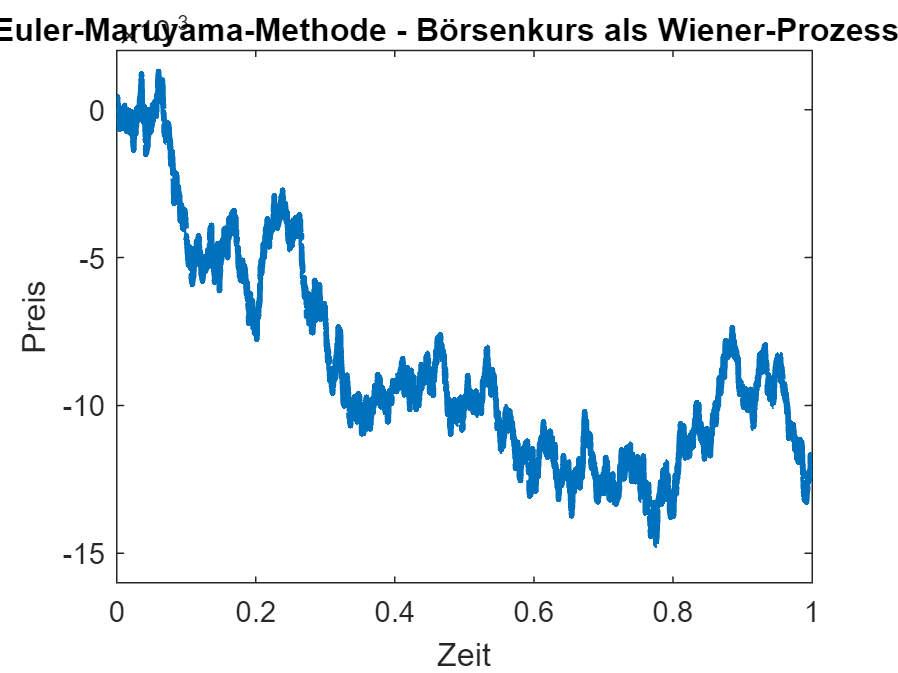

T = 1; 
N = 10000; 
dt = T/N; 
sigma = 1;
S0 = 0; 

dB = sqrt(dt)*randn(1,N);
S = zeros(1,N+1); 
S(1) = S0; 
for i = 1:N
    S(i+1) = S(i) + sigma*sqrt(dt)*dB(i);
end

plot(0:dt:T,S,'linewidth',2)
xlabel('Zeit')
ylabel('Preis')
title('Euler-Maruyama-Methode - Börsenkurs als Wiener-Prozesses')

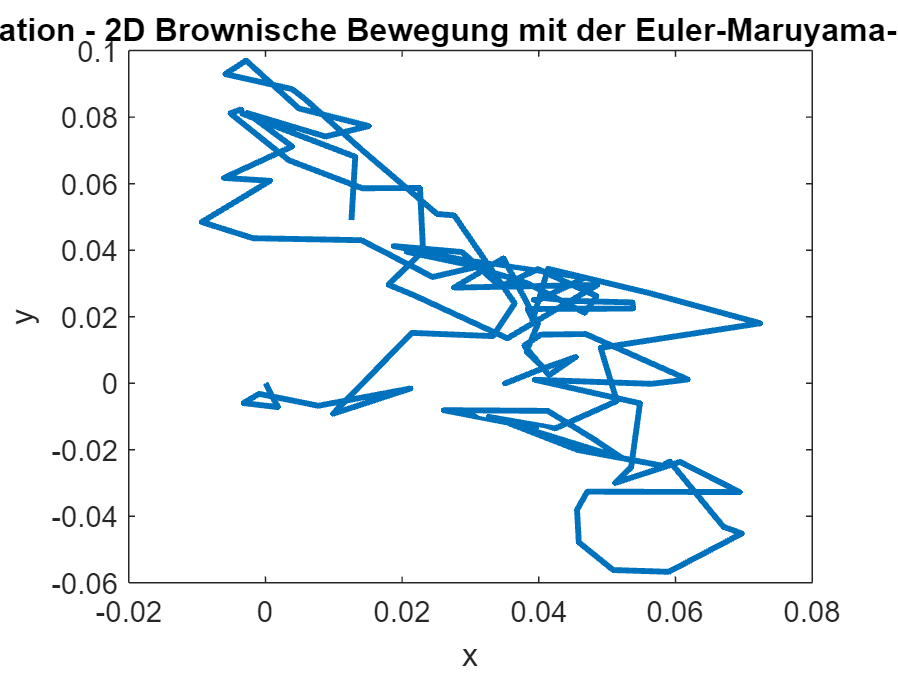

T = 1;
N = 100;
dt = T/N;
sigma = 1;
S0 = [0, 0];

dB = sqrt(dt)*randn(2, N);
S = zeros(2, N+1);
S(:,1) = S0';
for i = 1:N
    S(:,i+1) = S(:,i) + sigma*sqrt(dt)*dB(:,i);
end

plot(S(1,:),S(2,:),'linewidth',2)
xlabel('x')
ylabel('y')
title('Simulation - 2D Brownische Bewegung mit der Euler-Maruyama-Methode')

**Mimic Brownian motion / Noise through high frequency harmonic oscilaltions & Power spectrum**

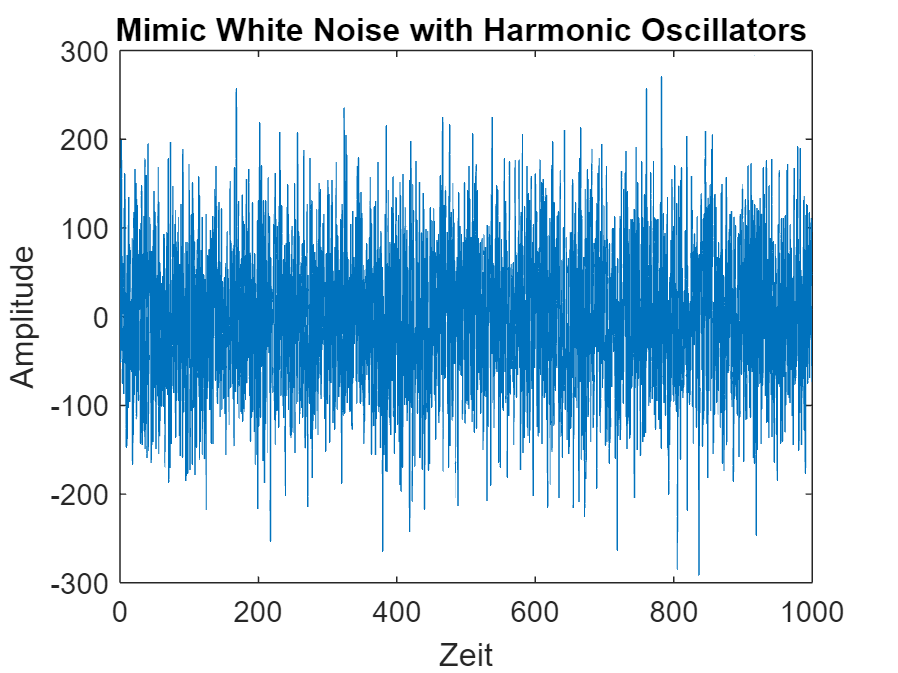


% Parameters for the simulation
num_oscillators = 10000;  % number of oscillators
t_end = 1000; % simulation end time
dt = 0.01; % time step size
t = 0:dt:t_end; % time vector

% Parameters for the oscillators
frequencies = randn(num_oscillators, 1); % frequencies of the oscillators
amplitudes = randn(num_oscillators, 1); % amplitudes of the oscillators
phases = 2*pi*rand(num_oscillators, 1); % phases of the oscillators

% Initialize the position vector
x = zeros(size(t));

% Calculate the position for each time point using all the oscillators
for i = 1:length(t)
    x(i) = sum(amplitudes .* cos(2*pi*frequencies*t(i) + phases));
end

figure
plot(t, x)
title('Mimic White Noise with Harmonic Oscillators ')
xlabel('Zeit')
ylabel('Amplitude')

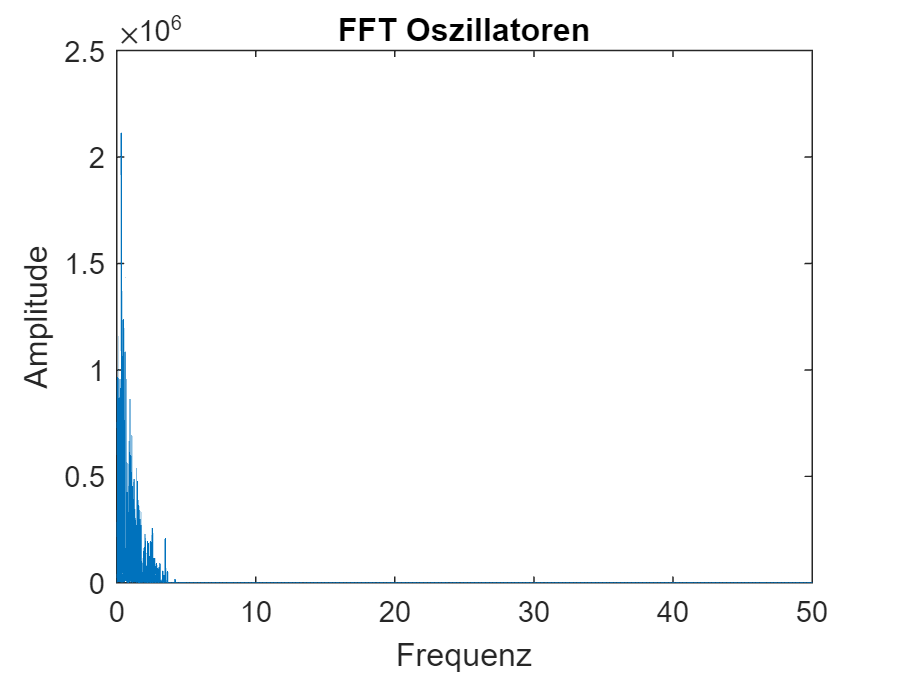


% Calculate the Fourier Transform of the signal
X = fft(x);

% Calculate the power spectrum (magnitude squared of each frequency component)
Pxx = abs(X).^2 / length(t);

% Frequency vector (considering only half the spectrum due to symmetry)
f = (0:(length(t)/2-1)) / (t_end); 

% Plot the power spectrum
figure
plot(f, Pxx(1:length(f)))
title('FFT Oszillatoren')
xlabel('Frequenz')
ylabel('Amplitude')

**Noise & Power Spectrum**

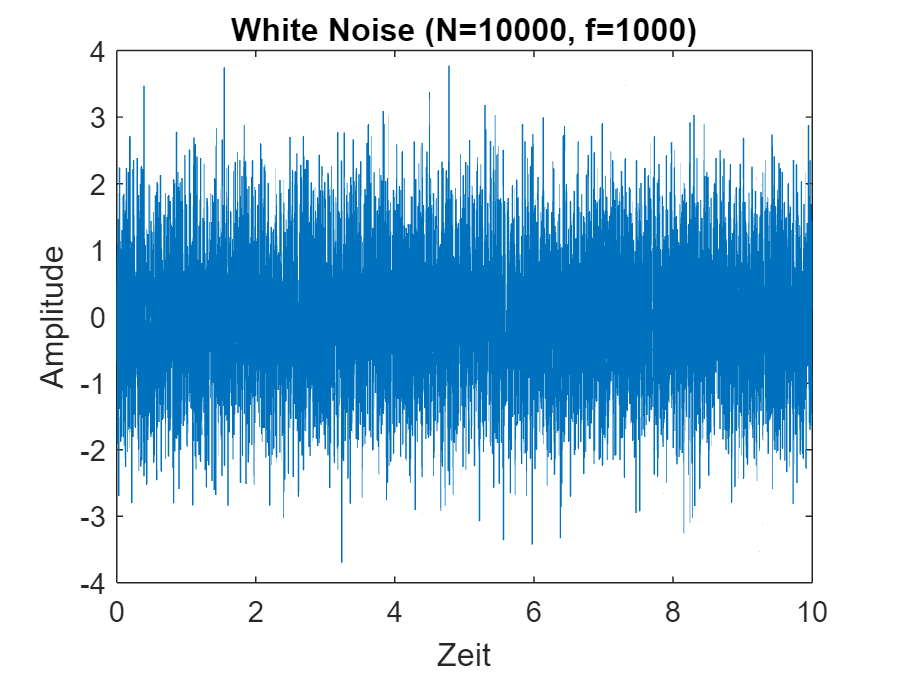

% Parameters
N = 10000;  % Number of samples
fs = 1000;  % Sampling rate in Hz
T = N/fs;   % Total time
t = (0:N-1)/fs;  % Time vector

% Generate white noise
noise = randn(1, N);

% Plot the noise signal
figure(1);
plot(t, noise);
xlabel('Zeit');
ylabel('Amplitude');
title('White Noise (N=10000, f=1000)');

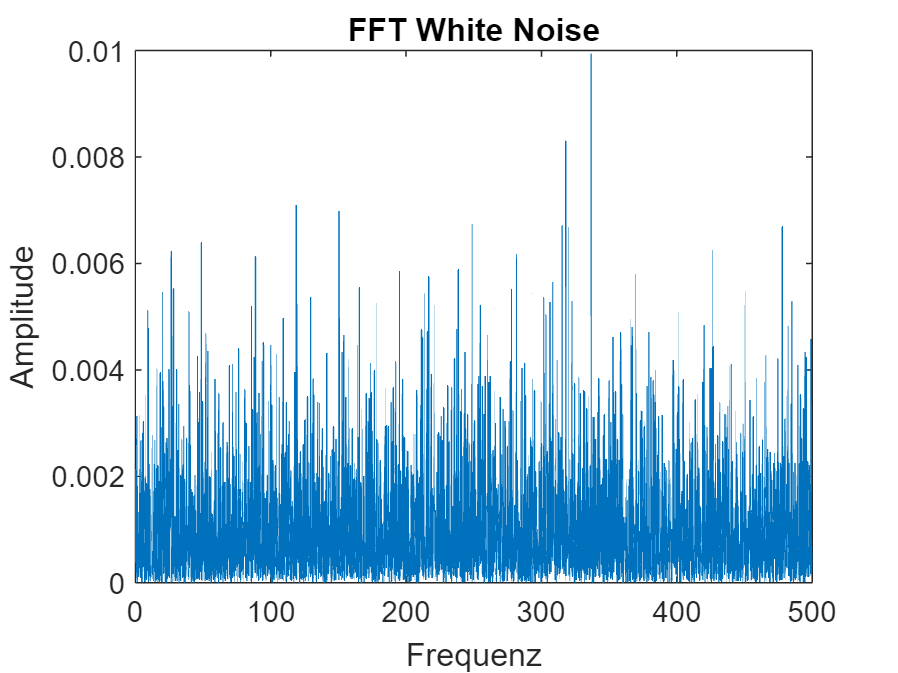


% Compute the Fourier transform
f_noise = fft(noise);

% Compute the power spectrum
Pxx = (1/(fs*N)) * abs(f_noise).^2;

% Frequency vector
f = 0:fs/N:fs/2;

% Plot the power spectrum
figure(2);
plot(f, Pxx(1:length(f)));
xlabel('Frequenz');
ylabel('Amplitude');
title('FFT White Noise');


% Show that power spectral density is approximately constant
mean_Pxx = mean(Pxx(1:length(f)));
disp(['Mean power spectral density: ', num2str(mean_Pxx)]);

Mean power spectral density: 0.0010093
